# Laboratorio di Automatica (prova del 28 August 2019)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

August 28, 2019

Dept. of Information Engineering, University of Padova

## Esercizio 3

Sia 


$$P(s)\,=\, \frac{\Theta(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


la funzione di trasferimento di un motore elettrico in corrente continua, da ingresso in tensione $u$ in $[V]$ ad uscita in *posizione* $\vartheta$ in $\mathrm{[rad]}$. Si supponga di controllare la *velocità* del motore ($\omega=d\vartheta/dt$) con uno schema di controllo in catena chiusa a tempo discreto del tipo mostrato in Fig. 1. 

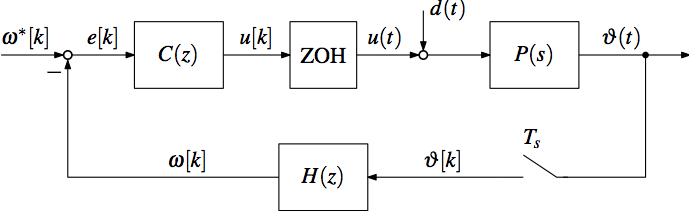

**Figura 1:** Sistema di controllo di velocità a tempo discreto.

Il controllore a tempo discreto $C(z)$ è la versione discretizzata, con il metodo di *Eulero all'Indietro* (*Backward Euler*), del seguente controllore a tempo continuo:


$$C(s)\,=\;\frac{k}{s} \left(\frac{1+\tau\,s}{1+\alpha\,\tau\,s}\right)\qquad\quad\text{con}\qquad\quad \alpha=0.17\,,\qquad\tau=0.015\,,\qquad k = 40$$


La funzione di trasferimento $C(s)$ è specificata assumendo come ingresso un errore di inseguimento $e(t)$ espresso in $\mathrm{[rad/s]}$, e come uscita un comando in tensione $u(t)$ espresso in $[V]$.

Il filtro $H(z)$ sul ramo di retroazione è usato per stimare la velocità $\omega$ a partire dalla misura di posizione $\vartheta$. E' la versione discretizzata, con il metodo di *Eulero all'Indietro* (*Backward Euler*), del seguente filtro "derivata reale" a tempo continuo:


$$H(s) \,=\, \frac{\omega_c^2\,\,s}{s^2 + 2 \delta\,\omega_c\,s + \omega_c^2} \qquad \text{con} \qquad \omega_c = (2\,\pi \times 150)\,\mathrm{rad/s}\,,\qquad \delta = \frac{1}{\sqrt{2}}$$


Considerando un un tempo di campionamento pari a $T_s = 0.001\,s$, si svolgano i seguenti punti:

1) Realizzare uno schema Simulink del sistema di controllo di velocità a tempo discreto illustrato in Fig. 1. Si assuma che:

- la tensione $u(t)$ sia fornita da un DAC (digital-to-analog converter) a 10 bit e range d uscita pari a $\pm\,10\,V$

- la misura di posizione $\vartheta[k]$ sia fornita da un encoder con risoluzione pari a $2000\,\mathrm{ppr}$ (*pulses-per-rotation*, ovvero impulsi-per-giro)

*Nota*: per simulare sia il campionatore che lo Zero-Order Holder (ZOH), si faccia ricorso al blocco `Discrete `$\rightarrow$` Zero-Order Hold` della libreria di blocchi del Simulink.

*Soluzione*.

%   conversion gains
deg2rad = pi/180;
rad2deg = 180/pi;
rads2rpm = 60/2/pi;
rpm2rads = 2*pi/60;
degs2rpm = 60/360;
rpm2degs = 360/60;

%   set plant params
km = 5.2;
Tm = 0.03;

%   set controller params
a = 0.17;
tau = 0.015;
k = 40;

%    DAC quantization interval [V/LSB]
qdac = 20/2^10; 

%    encoder quantization interval [deg/pulse]
qenc = 360/2000;

%   sampling time
Ts = 1e-3;

%   controller discretization (Backward Euler)
z = tf('z', Ts);
s = (1-z^-1)/Ts;
sysCd = k/s * (1+tau*s)/(1+a*tau*s);
[numCd, denCd] = tfdata(sysCd, 'v');

%   speed filter discretization (Backward Euler)
wc = 2*pi*150;
d = 1/sqrt(2);
sysHd = wc^2*s/(s^2 + 2*d*wc*s + wc^2);
[numHd, denHd] = tfdata(sysHd, 'v');

%    open Simulink model
open_system('ex3_sim1')

2) Simulare la risposta del sistema di controllo ad un riferimento di velocità $\omega^*$ a gradino di ampiezza pari a $A_r = 250\,rpm
$, applicato all'istante $t_{0,r} = 0.1\,s$. Si esegua la simulazione su un intervallo temporale di $0.5\,s$. Mostrare poi in una figura Matlab gli andamenti dei seguenti segnali:

- *plot 1:* velocità $\omega[k]$ e riferimento $\omega^*[k]$, entrambi espressi in $[\mathrm{rpm}]$ (rotations-per-minute, ovvero giri-al-minuto).

- *plot 2*: errore di inseguimento $e$, espresso in $[\mathrm{rpm}]$.

- *plot 3*: segnale di comando $u$, espresso in $[V]$.

*Nota*: nell'eseguire la simulazione, si faccia attenzione ad usare le stesse unità di misura per il segnale di riferimento $\omega^*$ e l'uscita di velocità $\omega$. 

Soluzione.

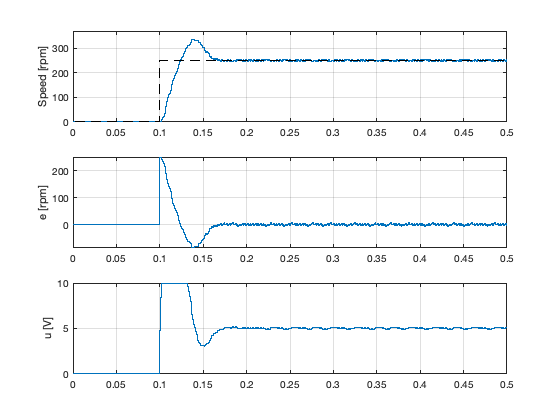

%    set reference params (amplitude & start time)
Ar = 250;  t0r = 0.1;  

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.001', 'StopTime','0.5');

%    run simulation
sim('ex3_sim1');

%   extract signals
t = simres.time;
y = simres.signals(1).values(:,1);
r = simres.signals(1).values(:,2);
e = simres.signals(2).values(:,1);
u = simres.signals(3).values(:,1);

%   plot results
figure;
subplot(3,1,1);
stairs(t, y);
hold on;
stairs(t, r, 'k--');
ylabel('Speed [rpm]');
grid on;
ylim([0,370]);

subplot(3,1,2);
stairs(t, e);
ylabel('e [rpm]');
grid on;

subplot(3,1,3);
stairs(t, u);
ylabel('u [V]');
grid on;

3) Al fine di ridurre l'overshoot nella risposta al gradino, si introduce lo schema di desaturazione dell'azione integrale riportato in Fig. 2. 

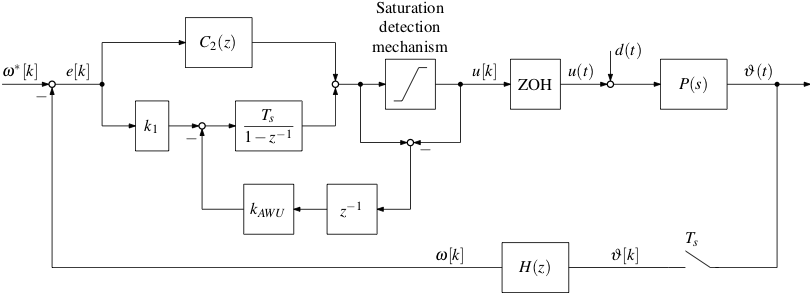

**Figura 2:** Sistema di controllo di velocità a tempo discreto, con schema di desaturazione dell'azione integrale.

Lo schema è ottenuto decomponendo inizialmente il controllore a tempo continuo$C(s)$ nella seguente realizzazione parallelo:


$$C(s) \;=\; C_1(s) \,+\, C_2(s) \;=\; \frac{k_1}{s} \,+\, \frac{k_2}{s+p_2} \qquad \text{con} \qquad p_2 = \frac{1}{\alpha\tau}$$
  

e discretizzando successivamente le due funzioni di trasferimento $C_1(s)$ e $C_2(s)$ con il metodo di Eulero all'Indietro.

Dopo aver determinato i guadagni $k_1$ e $k_2$ della realizzazione parallelo, e discretizzato la funzione di trasferimento $C_2(s)$, si realizzi uno schema Simulink del sistema di controllo riportato in Fig. 2. Per quanto riguarda lo schema di desaturazione dell'azione integrale, si utilizzi un blocco saturatore con gli stessi livelli di saturazione del DAC ($\pm\,10\,V$), e un guadagno di anti-windup pari a $k_{AWU} = 200$.

*Soluzione*.

La decomposizione parallelo del controllore $C(s)$ a tempo continuo è pari a:


$$C(s) \;=\; C_1(s) \,+\, C_2(s) 
\;=\; \frac{k_1}{s} \,+\, \frac{k_2}{s+p_2} 
\qquad \text{con} \qquad 
k_1 \,=\, k,\,\quad 
k_2 \,=\, k\,\left(\frac{1-\alpha}{\alpha}\right)\,,\quad
p_2 = \frac{1}{\alpha\tau}$$


%  continuos-time controller - parameters of parallel decomposition
p2 = 1/(a*tau);
k1 = k, k2 = k * (1-a)/a

k1 = 40

k2 = 195.2941

Il risultato può essere verificato numericamente utilizzando la routine `residue`: 

%  continuous-time controller tf
sysC = tf(k, [1,0]) * tf([tau, 1], [a*tau, 1]);
[numC, denC] = tfdata(sysC, 'v');

%  partial fraction expansion
[R, P, K] = residue(numC, denC);

Gains $k_1,\;k_2$ (residues):

k1 = R( P == 0 ), k2 = R( P ~= 0)

k1 = 40

k2 = 195.2941

%  controller discretization
k1 = k;
k2 = k * (1-a)/a;
p2 = 1/(a*tau);
sysC2d = k2/(s+p2);
[numC2d, denC2d] = tfdata(sysC2d, 'v');

%   anti-windup gain
kawu = 200;

%   open Simulink model
open_system('ex3_sim2')

4) Simulare la risposta del sistema di controllo con desaturazione dell'azione integrale riportato in Fig. 2. Mostrare i risultati in modo analogo a quanto fatto al punto 2.

*Soluzione*.

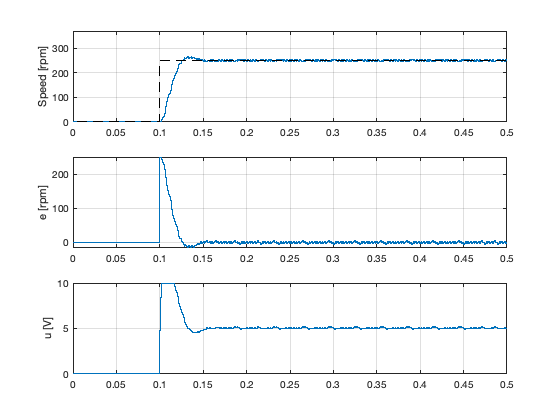

%    set simulation params
set_param('ex3_sim2', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.001', 'StopTime','0.5');

%    run simulation
sim('ex3_sim2');

%   extract signals
t = simres.time;
y = simres.signals(1).values(:,1);
r = simres.signals(1).values(:,2);
e = simres.signals(2).values(:,1);
u = simres.signals(3).values(:,1);

%   plot results
figure;
subplot(3,1,1);
stairs(t, y);
hold on;
stairs(t, r, 'k--');
ylabel('Speed [rpm]');
grid on;
ylim([0,370]);

subplot(3,1,2);
stairs(t, e);
ylabel('e [rpm]');
grid on;

subplot(3,1,3);
stairs(t, u);
ylabel('u [V]');
grid on;